N = 30;
% design vector x
% = [torque_Ls, torque_Rs, xs, ys, vs, thetas, thetadots, Tf]
x0 = [zeros(7*N,1); 1];

costfcn = @(x) x(end);

options = optimoptions('fmincon', 'MaxFunctionEvaluations', 1e5, 'Display', 'iter');
xstar = fmincon(costfcn, x0,[],[],[],[],[],[], @nonlcon, options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     212    1.000000e+00    5.000e+00    5.000e-01
    1     424    4.193548e-01    1.286e-01    5.000e-01    3.148e+01
    2     636    8.118521e-01    3.576e-02    5.000e-01    1.238e+01
    3     848    7.395826e-01    1.226e-03    5.000e-01    2.424e+00
    4    1060    7.366419e-01    4.519e-06    1.542e-01    9.530e-02
    5    1272    7.362019e-01    1.371e-06    1.000e-01    1.221e-01
    6    1484    7.354071e-01    2.930e-06    9.989e-02    1.508e-01
    7    1696    7.314813e-01    7.152e-05    9.936e-02    7.454e-01
    8    1908    7.184924e-01    7.802e-04    9.759e-02    2.463e+00
    9    2120    6.939598e-01    2.829e-03    9.426e-02    4.745e+00
   10    2332    6.840605e-01    4.854e-04    9.359e-02    2.043e+00
   11    2544    6.843917e-01    1.336e-06    9.359e-02    1.506e-01
   12    2756    6.815909e-01    3.457e-06    9

xstar =     2.9996
    2.9996
    2.9995
    2.9995
    2.9994
    2.9994
    2.9993
    2.9992
    2.9991
    2.9989


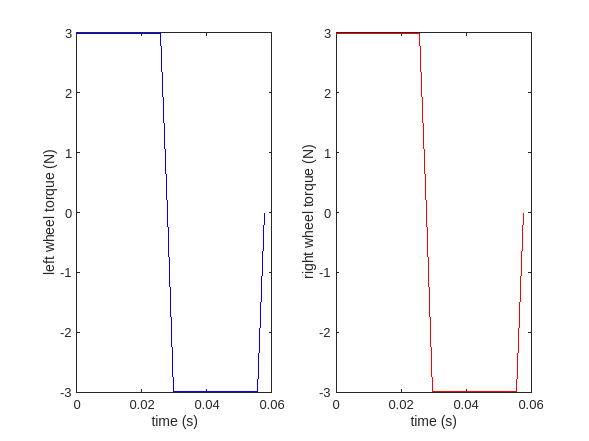


% Extract states from design vector
[ts, tauL, tauR, x, y, v, th, th_dot] = unpack_design_vector(xstar);

% Plot all states and trajectory
figure
hold on
subplot(1, 2, 1);
plot(ts, tauL, 'b-');
xlabel("time (s)")
ylabel("left wheel torque (N)")

subplot(1, 2, 2);
plot(ts, tauR, 'r-');
xlabel("time (s)")
ylabel("right wheel torque (N)")
hold off

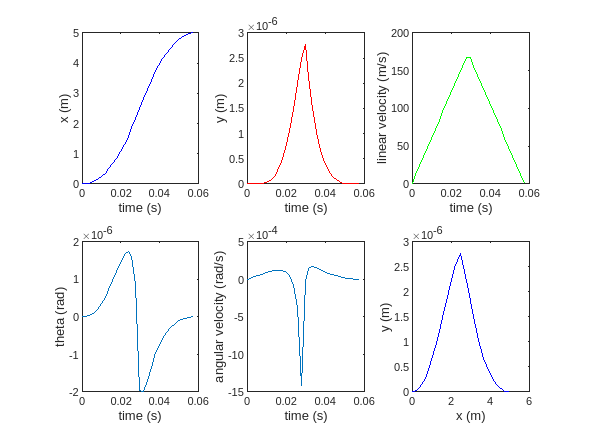


figure
hold on
subplot(2, 3, 1);
plot(ts, x, 'b-');
xlabel("time (s)")
ylabel("x (m)")

subplot(2, 3, 2);
plot(ts, y, 'r-');
xlabel("time (s)")
ylabel("y (m)")

subplot(2, 3, 3);
plot(ts, v, 'g-');
xlabel("time (s)")
ylabel("linear velocity (m/s)")

subplot(2, 3, 4)
plot(ts, th)
xlabel("time (s)")
ylabel("theta (rad)")

subplot(2, 3, 5);
plot(ts, th_dot)
xlabel("time (s)")
ylabel("angular velocity (rad/s)")

subplot(2, 3, 6);
plot(x, y, 'b-');
xlabel("x (m)")
ylabel("y (m)")
hold off

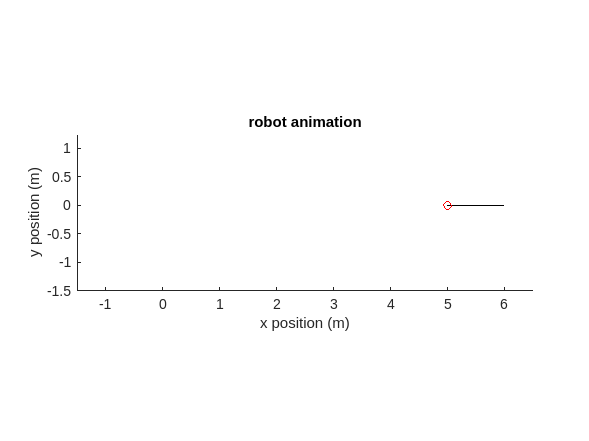


animate_direct_collocation(xstar)